**How to debug your code? **

% HW4-Q1
% https://grader.mathworks.com/courses/63549-w22-cive-121-homework/assignments/164724-homework-4/problems/580745-hw4-q1-locating-values-in-a-matrix
n = randi([25 50]); % A scalar value from 25 to 50
mat = randi([0 10],n,n); % An nxn matrix with random elements ranging from 0 to 10 

% Write your script here

mat = [8 1 1 1 7; 7  3 10 4 0; 1 6 10 10 9; 10 10 5 8 10; 6 10 8 10 7];

loc_vec = zeros(10,1);
count = 0;

mat_size = numel(mat);
for ii = 1:mat_size
    test_loc = mat(ii)
    
    if test_loc == 7
        count = count + 1;
        loc_vec(count) = ii;
    end
    
    if count == 10
        break
        
    end
end

test_loc = 8

test_loc = 7

test_loc = 1

test_loc = 10

test_loc = 6

test_loc = 1

test_loc = 3

test_loc = 6

test_loc = 10

test_loc = 10

test_loc = 1

test_loc = 10

test_loc = 10

test_loc = 5

test_loc = 8

test_loc = 1

test_loc = 4

test_loc = 10

test_loc = 8

test_loc = 10

test_loc = 7

test_loc = 0

test_loc = 9

test_loc = 10

test_loc = 7

How to  

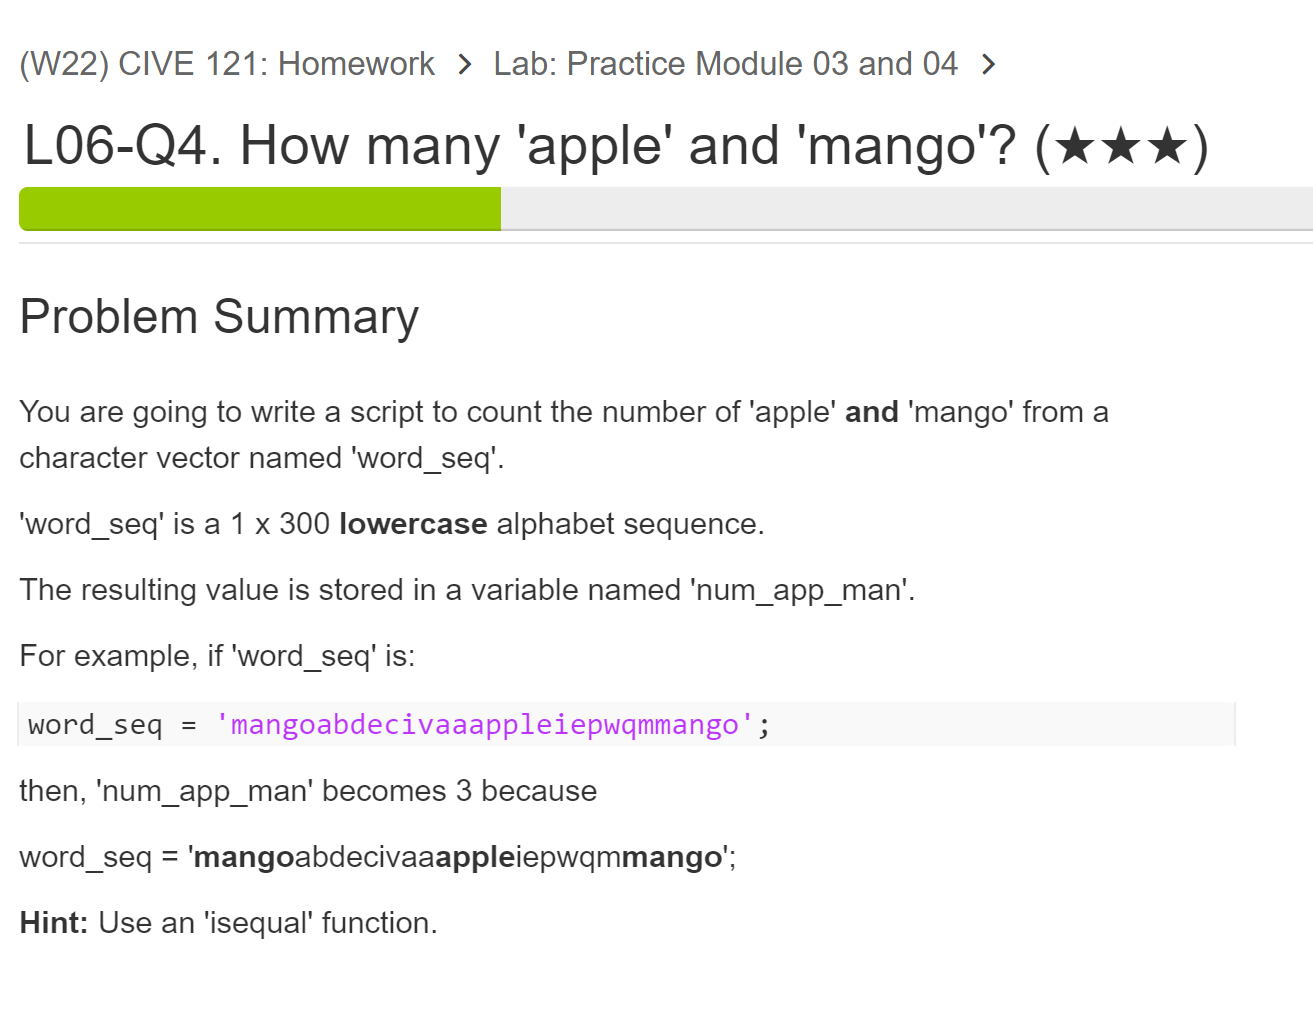

word_seq = char(randi([97 122], 1, 300)); % generate a random character sequece

n_word = randi([5 10]); 
wst = randi([1 290], 1, n_word); % starting word locations
wst_loc = reshape([wst;wst+1;wst+2;wst+3;wst+4], [], 1);

n1_word = round(n_word/2);
word_seq(wst_loc(1:(n1_word*5))) = repmat('apple', 1, n1_word); 
wst_loc(1:(n1_word*5)) = [];
word_seq(wst_loc) = repmat('mango', 1, numel(wst_loc)/5); 

clearvars wst wst_loc n_word n1_word

% Your Script Here
num_app_man = 0;

nseq = numel(word_seq);
ntest = 5;

% word_seq = 'mangoabdecivaaappleiepwqmmango';

for ii=1:nseq-ntest+1
    test_loc = ii:ii+ntest-1;
    if isequal(word_seq(test_loc), 'apple')
        num_app_man = num_app_man + 1;
    elseif isequal(word_seq(test_loc), 'mango')
        num_app_man = num_app_man + 1;
    end
end

fprintf('The word sequence is \n');

The word sequence is 


disp(word_seq); 

ngzpzbenqmangorgdbxmangogcweqnetpdlrhqyapplezenqukbndjsdubvwfpzbdfprsnqaftitwcpsmangosufcqaacvjfjeuiispapplekizgojiarxkwyjfehappleogahvxzatcquvoguehakawfwbfbtsxxuzuiatmkwbjdbsxjgxsxyyzkrvqsmnubxtqtapplejhtswxgrqbeiikcorcizxawgldfuckpapplekuapckzvbscmwavufxrxsmvcaimforvxlklimmangoxkcjegqzxbxezifyvysw



fprintf('\nA number of apple and mango in word_seq are %d. \n', num_app_man);


A number of apple and mango in word_seq are 9. 
